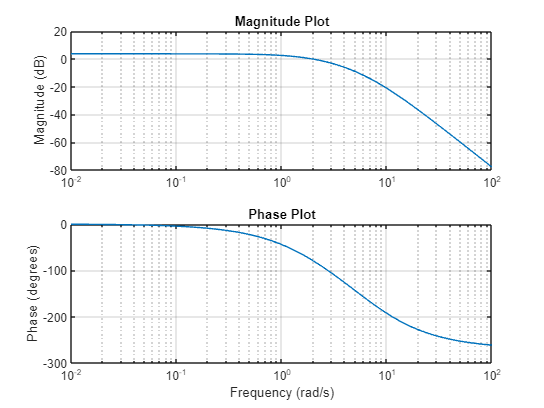

% Define the transfer function
s = tf('s');
k = 1;
G = (127*k)/((s+6)*(s+7)*(s+2));

% Plot the Bode plot
figure;
[mag, phase, wout] = bode(G, {1e-2, 1e2}); % Frequency range from 0.01 to 100 rad/s
mag = squeeze(mag);
phase = squeeze(phase);
wout = squeeze(wout);

% Plot magnitude
subplot(2,1,1);
semilogx(wout, 20*log10(mag));
title('Magnitude Plot');
ylabel('Magnitude (dB)');
grid on;

% Plot phase
subplot(2,1,2);
semilogx(wout, phase);
title('Phase Plot');
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
grid on;

% Set up data cursor
dcm_obj = datacursormode(gcf);

set(dcm_obj,'UpdateFcn',@myupdatefcn);

% Custom update function for data cursor

function txt = myupdatefcn(~, event_obj)
    % Obtain clicked position
    pos = get(event_obj, 'Position');
    freq = pos(1);
    
    % Find the closest frequency in wout
    [~, idx] = min(abs(wout - freq));

    % Display the information
    txt = {['Frequency: ', num2str(wout(idx)), ' rad/s'], ...
           ['Magnitude: ', num2str(20*log10(mag(idx))), ' dB'], ...
           ['Phase: ', num2str(phase(idx)), ' degrees']};
end